clc;close all;clear;

**Question6_1**

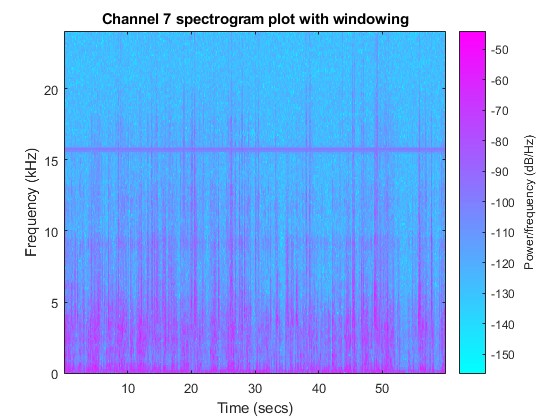


win_size = 0.004;
fft_overlap = 0.5;
[signal_C7, Fs] = audioread('c7m19.wav');
hop_size = Fs*win_size;
nfft = hop_size/fft_overlap;
noverlap = nfft-hop_size;
w = sqrt(hann(nfft));
figure
spectrogram(signal_C7, w ,noverlap, nfft, Fs, 'yaxis' );
colormap cool;
title('Channel 7 spectrogram plot with windowing');
figure

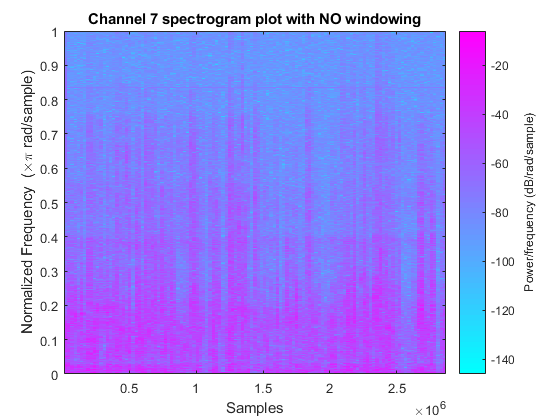

spectrogram(signal_C7, Fs, 'yaxis' );
colormap cool;
title('Channel 7 spectrogram plot with NO windowing');
[signal_C8, Fs_8] = audioread('c7m19.wav');

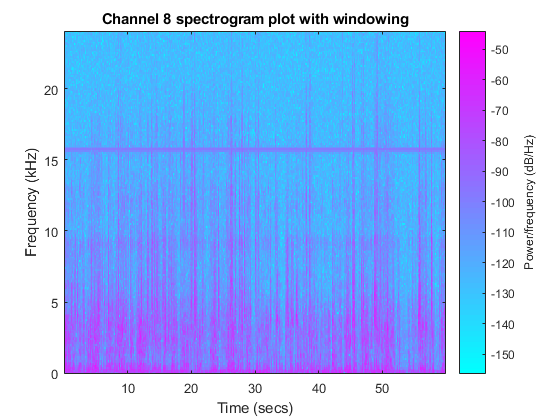

figure
spectrogram(signal_C8, w ,noverlap, nfft, Fs_8, 'yaxis' );
colormap cool;
title('Channel 8 spectrogram plot with windowing');
figure

spectrogram(signal_C8, Fs_8, 'yaxis' );
colormap cool;
title('Channel 8 spectrogram plot with NO windowing');

**Question6_2**

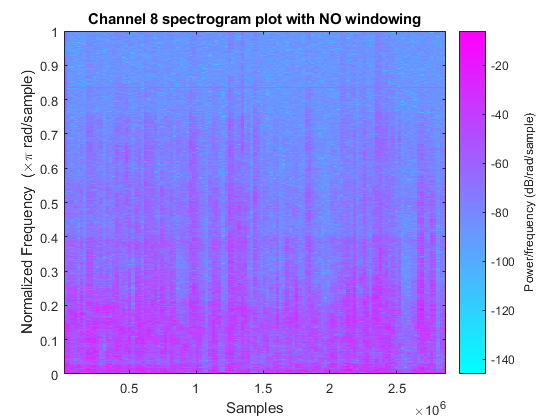

[data7,Fs7]= audioread('c7m19.wav');

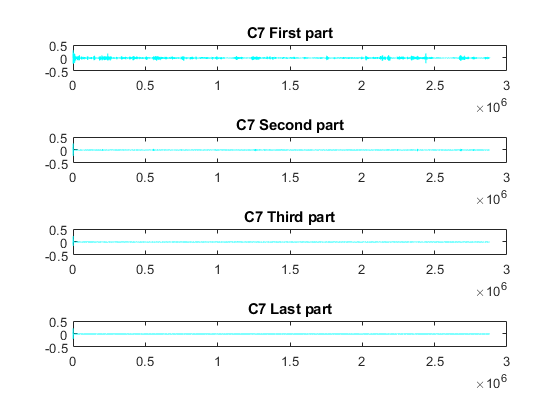


data_1 = filter(LP,data7); 
data_2 = filter(bp1,data7); 
data_3 = filter(bp2,data7); 
data_4 = filter(HP,data7);
figure
 subplot(4,1,1), plot(data_1,'c'), title('C7 First part')
 subplot(4,1,2), plot(data_2,'c'), title('C7 Second part')
 subplot(4,1,3), plot(data_3,'c'), title('C7 Third part')
 subplot(4,1,4), plot(data_4,'c'), title('C7 Last part')
[data8,Fs8]= audioread('c8m19.wav');
data_5 = filter(LP,data8); 

data_6 = filter(bp1,data8); 
data_7 = filter(bp2,data8); 
data_8 = filter(HP,data8);
figure
 subplot(4,1,1), plot(data_5,'c'), title('C8 First part')
 subplot(4,1,2), plot(data_6, 'c'), title('C8 Second part')
 subplot(4,1,3), plot(data_7 , 'c'), title('C8 Third part')
 subplot(4,1,4), plot(data_8, 'c'), title('C8 Last part')
 

**Question6_3**

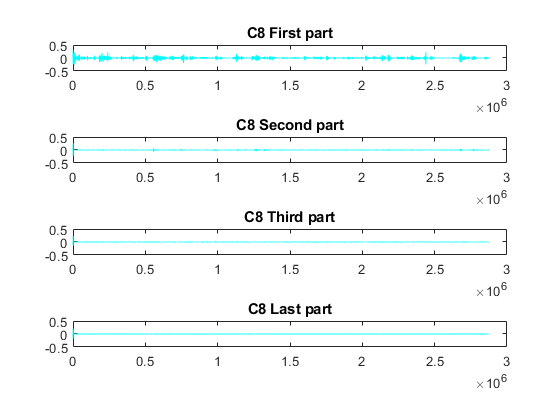

 %All_data = zeros(1220004,8);

 All_data(:,1) = decimate(data_1,4);
 All_data(:,2) = decimate(data_2,4);
 All_data(:,3) = decimate(data_3,4);
 All_data(:,4) = decimate(data_4,4);
 All_data(:,5) = decimate(data_5,4);
 All_data(:,6) = decimate(data_6,4);
 All_data(:,7) = decimate(data_7,4);
 All_data(:,8) = decimate(data_8,4);
 
 All_Chunked_channels = zeros(256,2812,8);
 for  data= 1:8
     for chunk= 1:2812
         start_index = 256*chunk-255;
         end_index = 256*chunk;
         All_Chunked_channels(:,chunk,data) = All_data(start_index:end_index,data);
     end
 end


**Question6_4**

 correlation_same_subchannels = zeros(2812,4);
 for sc = 1:4
     for chunk = 1:2812
         [~,correlation_same_subchannels(chunk,sc)] = max(abs(xcorr(All_Chunked_channels(:,chunk,sc),All_Chunked_channels(:,chunk,sc+4))));
     end
 end
figure
for i = 1:4
 subplot(4,1,i),histogram(correlation_same_subchannels(:,i)), title(['subchannel NO.',i,' lagindex distrbution ']),xlim([0  600]);
end

**Question6_5**

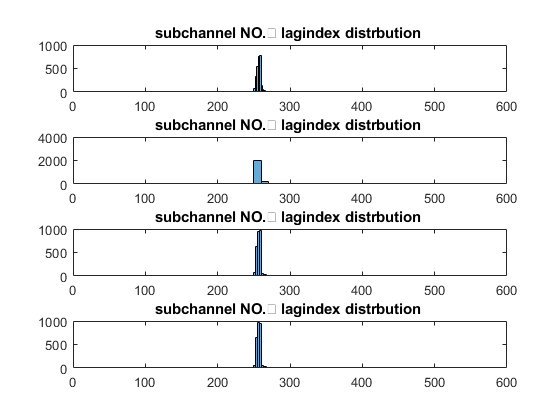

figure
for i = 1:4
 subplot(4,1,i),histfit(correlation_same_subchannels(:,i)), title(['subchannel NO.',i,' lagindex distrbution with Normal fit distribution']),xlim([0  600]);

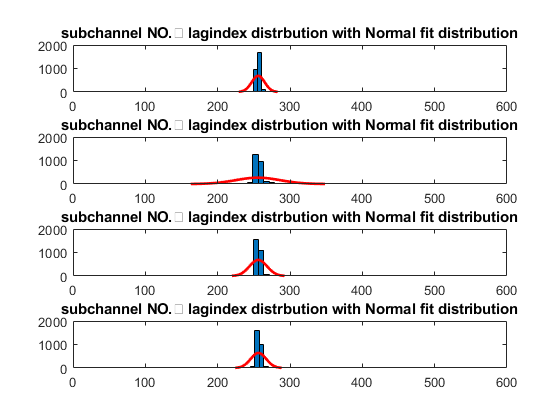

end
 first_channel = fitdist(correlation_same_subchannels(:,1),'Normal');
 display(first_channel);
 second_channel = fitdist(correlation_same_subchannels(:,2),'Normal');
 display(second_channel);
 third_channel = fitdist(correlation_same_subchannels(:,3),'Normal');
 display(third_channel);

 last_channel = fitdist(correlation_same_subchannels(:,4),'Normal');
 display(last_channel);

first_channel =   NormalDistribution

  Normal distribution
       mu = 255.991   [255.659, 256.323]
    sigma = 8.97478   [8.74621, 9.21571]


second_channel =   NormalDistribution

  Normal distribution
       mu = 255.627   [254.483, 256.771]
    sigma = 30.9389   [30.1509, 31.7695]


**Question7**

 W_ch_n = zeros(4,2812);

third_channel =   NormalDistribution

  Normal distribution
       mu = 256.127   [255.678, 256.575]
    sigma = 12.1331   [11.8241, 12.4588]


 a=zeros(4,2812);
 sigma = [0.03;.5;.5;.5];

last_channel =   NormalDistribution

  Normal distribution
       mu = 256.365   [255.97, 256.761]
    sigma = 10.6976   [10.4252, 10.9848]


 mu = [256;256;256;256];
 for ch = 1:4
     for n = 1:2812
         temp = (correlation_same_subchannels(n,ch)-mu(ch)).^2;
         W_ch_n(ch,n) = (exp(-temp./(2.*(sigma(ch)).^2)));
     end
 end
 %%
 figure

 

Question8

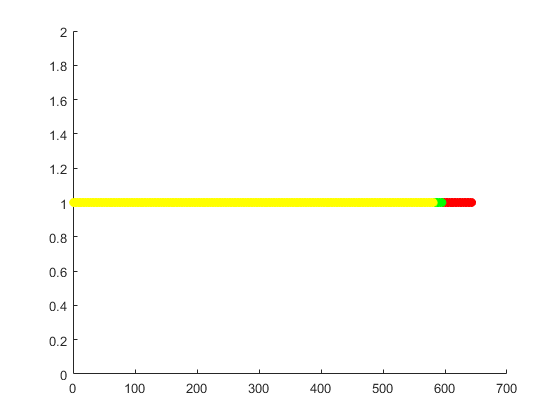

  
 for i=1:4
     for j=1:2812
     weighted_chunkso(:,j,i)=All_Chunked_channels(:,j,i).*W_ch_n(i,j);
     weighted_chunkso(:,j,i+4)=All_Chunked_channels(:,j,i+4).*W_ch_n(i,j);
     end

 end
 routput = zeros(2880016,1);
 loutput = zeros(2880016,1);
 interpolated_weighted_chunkr = zeros(720004,8)
  for j=1:8
    for i=1:2812
     interpolated_weighted_chunkr(256*(i-1)+1:256*i,j)=weighted_chunkso(:,i,j);
    end
  end
  for i=1:8
      interpolated_weighted_chunksr(:,i)=interp(interpolated_weighted_chunkr(:,i),4);
  end 
  for i=1:4
      routput(:,1)=routput(:,1)+interpolated_weighted_chunksr(:,i);

interpolated_weighted_chunkr =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


  end
   for i=1:4
      loutput(:,1)=loutput(:,1)+interpolated_weighted_chunksr(:,i);
   end
   audiowrite('Rightoutput.wav',routput,Fs);
   audiowrite('Leftoutput.wav',loutput,Fs);

questipon9

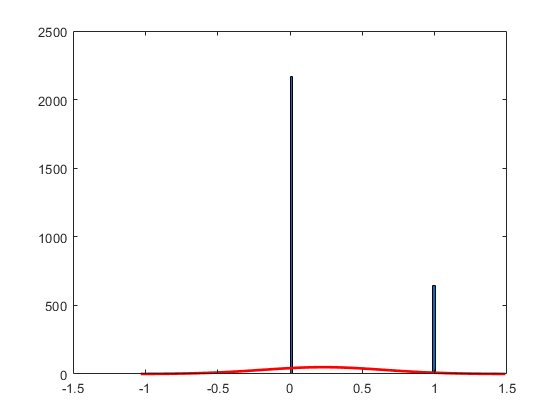

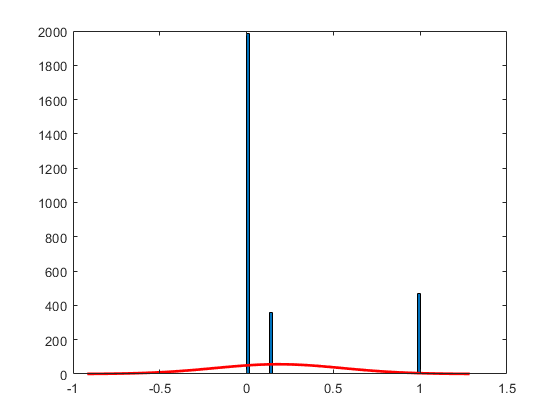

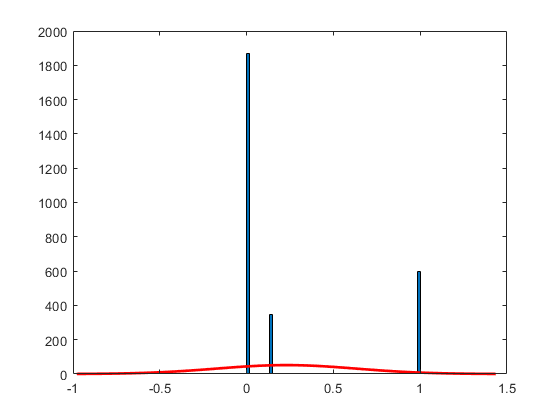

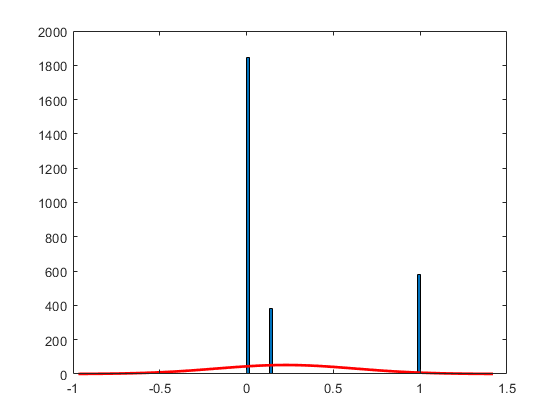

 
   smooth_wight=zeros(4,2812);
 for i=1:4
 smooth_wight(i,:)= smooth(W_ch_n(i,:));
 figure
 histfit(W_ch_n(i,:));
 %hold on;
 %hist(smooth_wight(i,:),'--');
 end
 figure
plot(smooth_wight(1,:))
figure
plot(W_ch_n(2,:))
figure
plot(smooth_wight(2,:))
figure
plot(W_ch_n(3,:))
figure
plot(W_ch_n(3,:))
figure
plot(smooth_wight(3,:))

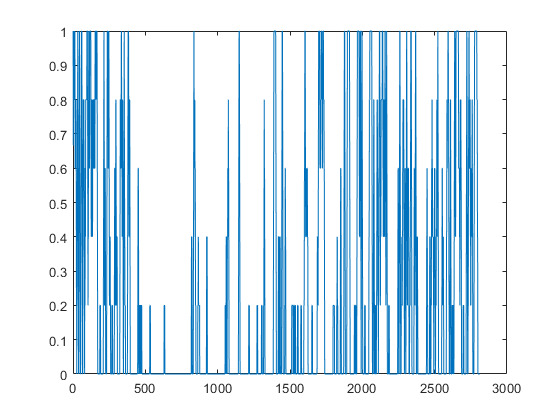

figure
plot(W_ch_n(4,:))

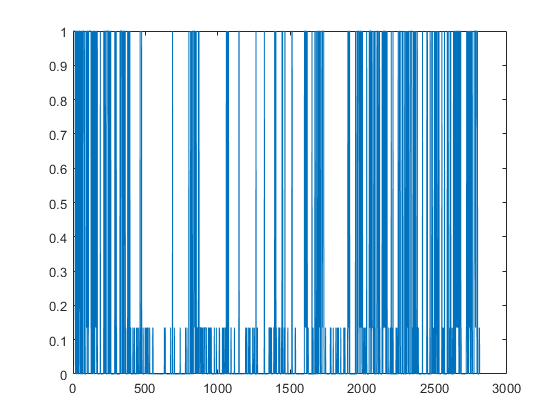

figure
plot(smooth_wight(4,:))

Question10

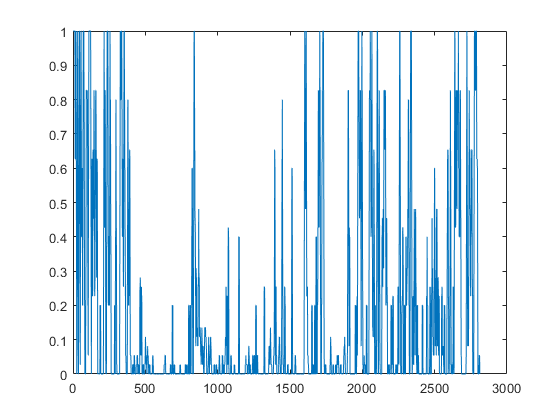

weighted_chunk=zeros(256,11250,8);
 for i=1:4

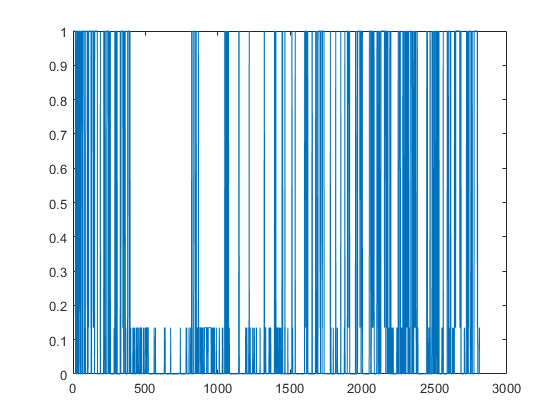

     for j=1:2812
     weighted_chunk(:,j,i)=All_Chunked_channels(:,j,i).*smooth_wight(i,j);

     weighted_chunk(:,j,i+4)=All_Chunked_channels(:,j,i+4).*smooth_wight(i,j);
     end

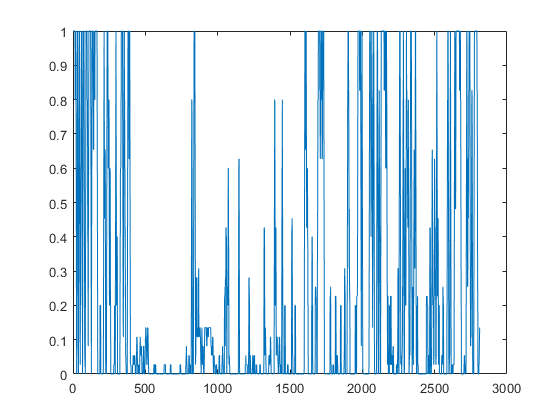

 end
 nroutput = zeros(2880016,1)

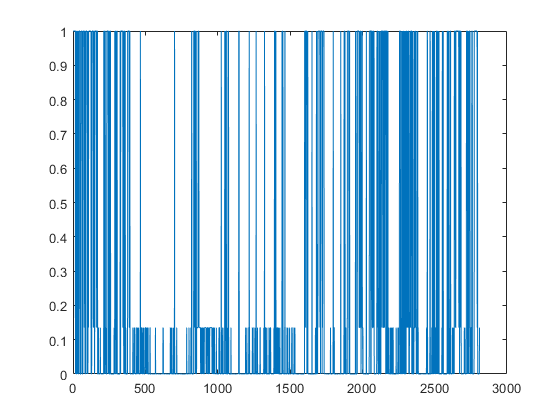

 lroutput = zeros(2880016,1)
 toutput = zeros(2880016,1)

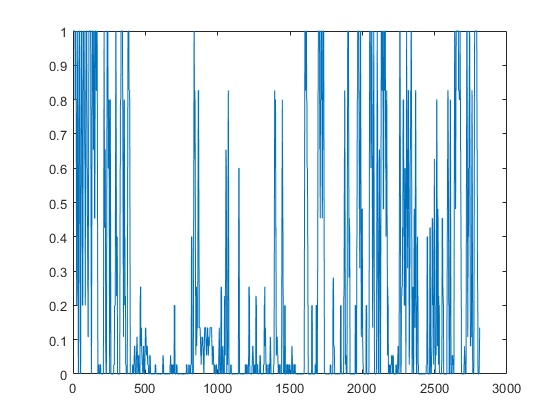

 interpolated_weighted_chunk = zeros(720004,8)
  for j=1:8

    for i=1:2812
     interpolated_weighted_chunk(256*(i-1)+1:256*i,j)=weighted_chunk(:,i,j);
    end
  end
  for i=1:8
      interpolated_weighted_chunks(:,i)=interp(interpolated_weighted_chunk(:,i),4);
  end 
  for i=1:8
      toutput(:,1)=toutput(:,1)+interpolated_weighted_chunks(:,i);
  end

nroutput =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


  for i=1:4

lroutput =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


      nroutput(:,1)=nroutput(:,1)+interpolated_weighted_chunks(:,i);

toutput =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


  end

interpolated_weighted_chunk =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


  for i=5:8
      lroutput(:,1)=lroutput(:,1)+interpolated_weighted_chunks(:,i);
  end
  so=smooth(toutput);
  x=linspace(0,2880016,10000);
  figure
  plot(so);
audiowrite('Left_smoothed_output.wav',lroutput,Fs);
audiowrite('right_smoothed_output.wav',nroutput,Fs);
audiowrite('Sum_smooth_output.wav',so,Fs);

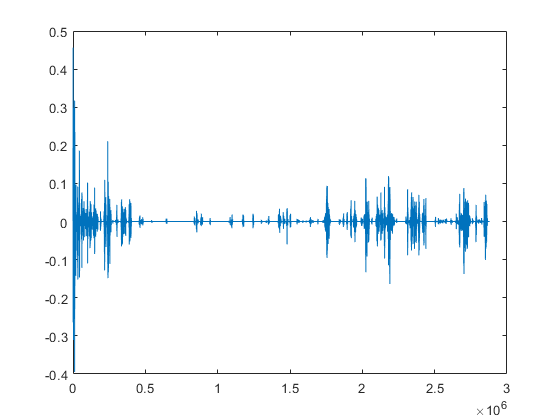

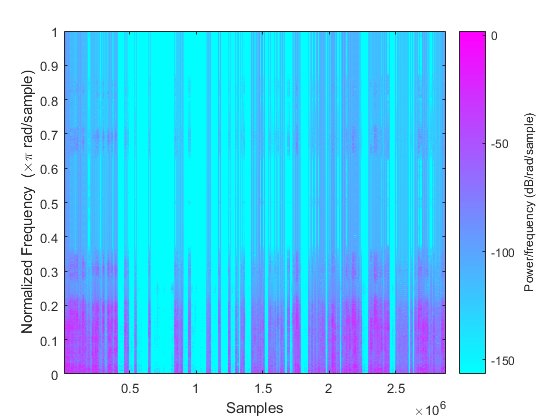

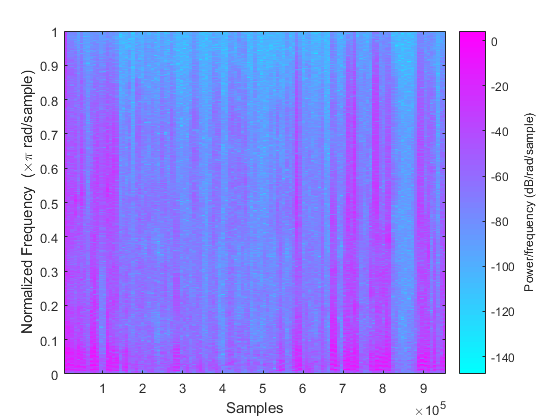

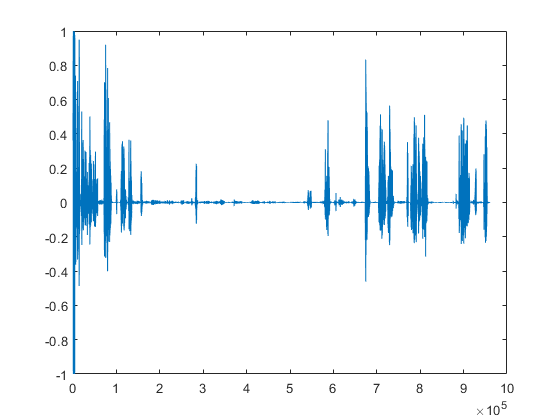

spectrogram(so, Fs, 'yaxis' );
colormap cool
[solo, Fs] = audioread('c3m19.wav');
spectrogram(solo, Fs, 'yaxis' );
colormap cool
plot(solo)
